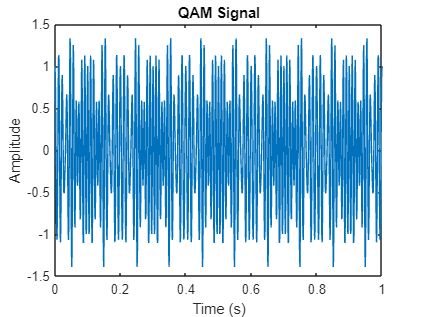

% Given parameters
fm = 10; % Hz
fm1 = 15; % Hz
fs = 1000; % Hz
fc = 100; % Hz

% Define time vector
t = 0:1/fs:1;

% Define message 1 as cos(2*pi*fm*t) and plot
message1 = cos(2*pi*fm*t);

% Define message 2 as sin(2*pi*fm1*t) and plot
message2 = sin(2*pi*fm1*t);

% Take carrier 1 as cos(2*pi*fc*t) and plot
carrier1 = cos(2*pi*fc*t);

% Take carrier 2 as sin(2*pi*fc*t) and plot
carrier2 = sin(2*pi*fc*t);

% Perform AM modulation of the both signals by multiplying the both messages with its respective carrier
modulated_signal1 = message1 .* carrier1;
modulated_signal2 = message2 .* carrier2;

% Add both modulated signals for QAM
qam_signal = modulated_signal1 + modulated_signal2;
% Plot the result of QAM modulation
figure;
plot(t, qam_signal);
title('QAM Signal');
xlabel('Time (s)');
ylabel('Amplitude');

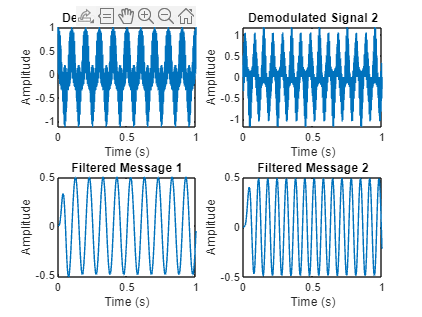



% Multiply QAM signal with respective carriers for QAM demodulation
demod_signal1 = qam_signal .* carrier1;
demod_signal2 = qam_signal .* carrier2;

% Plot demodulated signal 2
subplot(2, 2, 1);
plot(t, demod_signal1);
title('Demodulated Signal 1');
xlabel('Time (s)');
ylabel('Amplitude');

% Plot demodulated signal 2
subplot(2, 2, 2);
plot(t, demod_signal2);
title('Demodulated Signal 2');
xlabel('Time (s)');
ylabel('Amplitude');

% Design Low Pass Butterworth filter for message signals requirements
% Define filter parameters
cutoff_frequency = 20; % Hz
order = 5; % Filter order
[b, a] = butter(order, cutoff_frequency/(fs/2), 'low');

% Apply filter to message signals
filtered_message1 = filter(b, a, demod_signal1);
filtered_message2 = filter(b, a, demod_signal2);

% Plot filtered messages
subplot(2, 2, 3);
plot(t, filtered_message1);
title('Filtered Message 1');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2, 2, 4);
plot(t, filtered_message2);
title('Filtered Message 2');
xlabel('Time (s)');
ylabel('Amplitude');